L5 Primera Part                                                                                                                                                   Marta Granero i Martí

Exercici 1

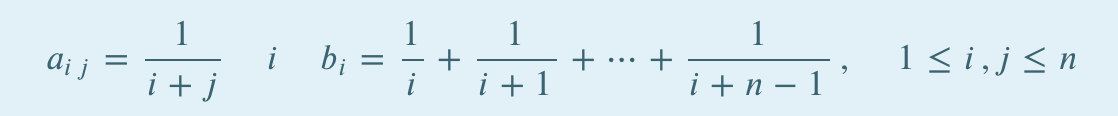

a) Com canvia el nombre de condició d’aquesta matriu quan l’ordre creix? Presenta un estudi per 𝑛 = 3,4,…,10,…15

%Per n = 3
n = 3;
a3 = zeros(n,n);
for (i = 1:n)
    for (j = 1:n)
        a3(i,j) = 1/(i+j);
    end
end

b3 = zeros(n,0);
for (i = 1:n)
    b3(i) = 1/i;
end
a3;
b3;
per3 = cond(a3,1);
array2table(per3, 'VariableNames',{'Nombre de condició: n = 3'})

ans = table
    Nombre de condició: n = 3
    _________________________

              2015           


%Per n = 4
n = 4;
a4 = zeros(n,n);
for (i = 1:n)
    for (j = 1:n)
        a4(i,j) = 1/(i+j);
    end
end

b4 = zeros(n,0);
for (i = 1:n)
    b4(i) = 1/i;
end
per4 = cond(a4,1);
array2table(per4, 'VariableNames',{'Nombre de condició: n = 4'})

ans = table
    Nombre de condició: n = 4
    _________________________

              81389          


%Per n = 10
n = 10;
a10 = zeros(n,n);
for (i = 1:n)
    for (j = 1:n)
        a10(i,j) = 1/(i+j);
    end
end

b10 = zeros(n,0);
for (i = 1:n)
    b10(i) = 1/i;
end
per10 = cond(a10,1);
array2table(per10, 'VariableNames',{'Nombre de condició: n = 10'})

ans = table
    Nombre de condició: n = 10
    __________________________

            1.3285e+14        


%Per n = 15
n = 15;
a15 = zeros(n,n);
for (i = 1:n)
    for (j = 1:n)
        a15(i,j) = 1/(i+j);
    end
end

b15 = zeros(n,0);
for (i = 1:n)
    b15(i) = 1/i;
end
per15 = cond(a15,1);

array2table(per15, 'VariableNames',{'Nombre de condició: n = 15'})

ans = table
    Nombre de condició: n = 15
    __________________________

            5.7515e+17        


%A mesura que n augmenta el nombre de condició també ho fa
valors = [per3;per4;per10;per15];
nombreCondicio = ["n = 3"; "n = 4"; "n = 10"; "n = 15"];
taula = table(nombreCondicio,valors)

taula = 4×2 table
    nombreCondicio      valors  
    ______________    __________

       "n = 3"              2015
       "n = 4"             81389
       "n = 10"       1.3285e+14
       "n = 15"       5.7515e+17


b) Resoleu el sistema lineal per eliminació gaussiana sense pivotament. Presenta un estudi per 𝑛 = 3÷10

tic
x3 = ElimGaussSensePivot(a3,b3');
tempsGauss3 = toc

tempsGauss3 = 0.0180


tic
x4 = ElimGaussSensePivot(a4,b4');
tempsGauss4 = toc

tempsGauss4 = 0.0080


tic
x10 = ElimGaussSensePivot(a10,b10');
tempsGauss10 = toc

tempsGauss10 = 0.0151


tempsGauss = [tempsGauss3;tempsGauss4;tempsGauss10];

x15 = ElimGaussSensePivot(a15,b15');

c) Resoleu el sistema lineal fent ús de les funcions de Matlab® decompositon i linsolve. Presenta un estudi per 𝑛 = 3,4,…,10,…

tic
sol3 = linsolve(a3,b3');
tempsSolve3 = toc

tempsSolve3 = 0.0041


tic
sol4 = linsolve(a4,b4');
tempsSolve4 = toc

tempsSolve4 = 0.0036


tic
sol10 = linsolve(a10,b10');
tempsSolve10 = toc

tempsSolve10 = 0.0085


tempsSolve = [tempsSolve3;tempsSolve4;tempsSolve10];

sol15 = linsolve(a15,b15');

d) Resoleu el sistema lineal pel mètode de Gauss-Seidel. Presenta un estudi per 𝑛=3÷10

% Càlculs per fer n = 3
tic
D = diag(diag(a3));
d = diag(1 ./ diag(a3));

L = tril(a3,-1);
U = triu(a3,1);
dG = inv(L+D);
Bgs = -dG*U; %matriu iteració
cgs = dG*b3'; %vector

rhoGS = max(abs(eig(Bgs))); %radi espectral del mètode de Gauss-Seidel

if (rhoGS + eps >= 1) resp = "mètode de GAUSS-SEIDEL divergent";
else resp = "mètode de GAUSS-SEIDEL convergent";
end

gauss = {rhoGS, resp}';

table(gauss, 'VariableNames',{'Gauss-Seidel'})

ans = 2×1 table
                 Gauss-Seidel              
    _______________________________________

    {[                             0.9943]}
    {["mètode de GAUSS-SEIDEL convergent"]}



%mètode de Gauss
clear residu criteriParada e delta
if rhoGS >=1
    error('mètode de gauss-seidel divergent')
else
    n = 1000; i = 0; 
    x = zeros(size(b3'));
    tol = 0.5e-8;
    criteriParada(1) = 1;
    while(i<n && criteriParada(max(i,1)) > tol)
        i = i+1; y = Bgs*x+cgs;
        residu(i) = norm(b3'-a3*y,'inf');
        e(i) = norm(y-x,'inf');
        delta(i) = norm(y-x,'inf');
        criteriParada(i) = delta(i)/norm(y,'inf');
        x = y;
    end
    tempsGaussSeidel3 = toc
    table(residu',e',delta',criteriParada','VariableNames',{'residu','e^k','delta^k','stop'})
    table(i, residu(1), residu(end), 'VariableNames',{'# iteracions', 'Primer Residu', 'Darrer Residu'})
    x(1);
end 

tempsGaussSeidel3 = 0.2580

ans = 1000×4 table
     residu       e^k      delta^k      stop  
    ________    _______    _______    ________

     0.27222          2          2           1
     0.22303    0.56593    0.56593     0.22242
     0.18343     0.4847     0.4847     0.16208
     0.15155    0.41919    0.41919     0.12486
     0.12587    0.36631    0.36631     0.10007
     0.10519     0.3236     0.3236    0.082716
    0.088527    0.28907    0.28907     0.07012
      0.0751    0.26113    0.26113    0.060733
    0.064274    0.23849    0.23849    0.053594
    0.055543    0.22011    0.22011    0.048075
    0.048496    0.20516    0.20516    0.043748
    0.042804    0.19297    0.19297    0.040316
    0.038203      0.183      0.183    0.037562
     0.03448    0.17483    0.17483     0.03533
    0.031463     0.1681     0.1681    0.033502
    0.029015    0.16252    0.16252     0.0319

ans = 1×3 table
    # iteracions    Primer Residu    Darrer Residu
    ____________    _____________    _____________

        1000           0.27222        8.2706e-05  


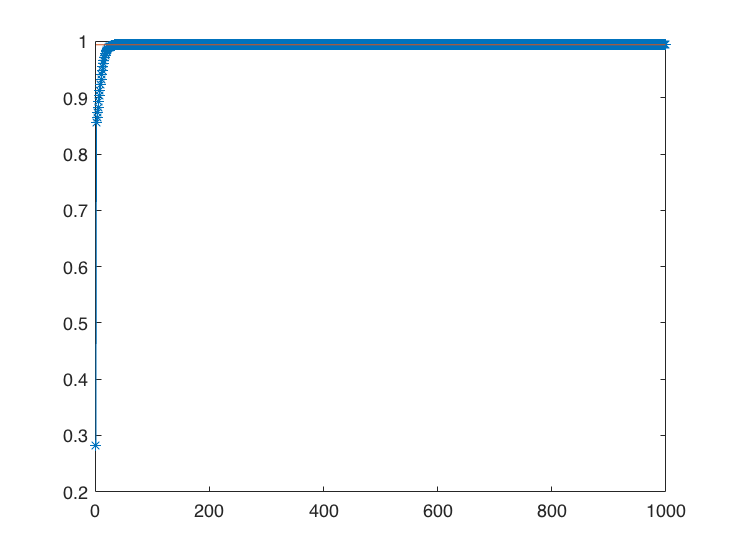

%És interessant estudiar com evoluciona: delta^k/delta^k-1
ratio = delta(2:end) ./ delta(1:end-1);
plot(ratio,'-*')
hold on
plot(rhoGS * ones(size(ratio)))
hold off

% Càlculs per fer n = 4
tic
D = diag(diag(a4));
d = diag(1 ./ diag(a4));

L = tril(a4,-1);
U = triu(a4,1);
dG = inv(L+D);
Bgs = -dG*U; %matriu iteració
cgs = dG*b4'; %vector

rhoGS = max(abs(eig(Bgs))); %radi espectral del mètode de Gauss-Seidel

if (rhoGS + eps >= 1) resp = "mètode de GAUSS-SEIDEL divergent";
else resp = "mètode de GAUSS-SEIDEL convergent";
end

gauss = {rhoGS, resp}';
%table(gauss, 'VariableNames',{'Gauss-Seidel'})

%mètode de Gauss
clear residu criteriParada e delta
if rhoGS >=1
    error('mètode de gauss-seidel divergent')
else
    n = 1000; i = 0; 
    x = zeros(size(b4'));
    tol = 0.5e-8;
    criteriParada(1) = 1;
    while(i<n && criteriParada(max(i,1)) > tol)
        i = i+1; y = Bgs*x+cgs;
        residu(i) = norm(b4'-a4*y,'inf');
        e(i) = norm(y-x,'inf');
        delta(i) = norm(y-x,'inf');
        criteriParada(i) = delta(i)/norm(y,'inf');
        x = y;
    end
    tempsGaussSeidel4 = toc
    table(residu',e',delta',criteriParada','VariableNames',{'residu','e^k','delta^k','stop'})
    table(i, residu(1), residu(end), 'VariableNames',{'# iteracions', 'Primer Residu', 'Darrer Residu'})
    x(1);
end 

tempsGaussSeidel4 = 0.0426

ans = 1000×4 table
     residu       e^k      delta^k      stop  
    ________    _______    _______    ________

     0.28873          2          2           1
     0.22456    0.57746    0.57746     0.22404
     0.17679    0.47119    0.47119     0.15568
     0.14119    0.40827    0.40827     0.12078
     0.11464    0.36079    0.36079    0.098509
    0.094794     0.3248     0.3248    0.083458
    0.079932    0.29734    0.29734    0.072852
    0.068769    0.27622    0.27622    0.065127
    0.060354    0.25982    0.25982    0.059335
    0.053981    0.24693    0.24693    0.054879
    0.049124    0.23665    0.23665    0.051363
    0.045395    0.22833    0.22833    0.048522
    0.042504    0.22147    0.22147    0.046173
    0.040238     0.2157     0.2157    0.044186
    0.038437    0.21075    0.21075     0.04232
    0.036982    0.20641    0.20641      0.039

ans = 1×3 table
    # iteracions    Primer Residu    Darrer Residu
    ____________    _____________    _____________

        1000           0.28873         0.0028225  


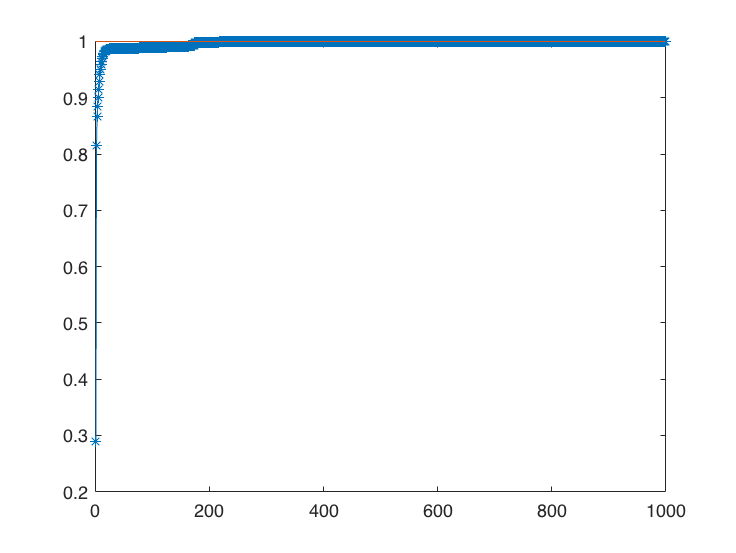

%És interessant estudiar com evoluciona: delta^k/delta^k-1
ratio = delta(2:end) ./ delta(1:end-1);
plot(ratio,'-*')
hold on
plot(rhoGS * ones(size(ratio)))
hold off

% Càlculs per fer n = 10
tic
D = diag(diag(a10));
d = diag(1 ./ diag(a10));

L = tril(a10,-1);
U = triu(a10,1);
dG = inv(L+D);
Bgs = -dG*U; %matriu iteració
cgs = dG*b10'; %vector

rhoGS = max(abs(eig(Bgs))); %radi espectral del mètode de Gauss-Seidel

if (rhoGS + eps >= 1) resp = "mètode de GAUSS-SEIDEL divergent";
else resp = "mètode de GAUSS-SEIDEL convergent";
end

gauss = {rhoGS, resp}';
%table(gauss, 'VariableNames',{'Gauss-Seidel'});

%mètode de Gauss
clear residu criteriParada e delta
if rhoGS >=1
    error('mètode de gauss-seidel divergent')
else
    n = 1000; i = 0; 
    x = zeros(size(b10'));
    tol = 0.5e-8;
    criteriParada(1) = 1;
    while(i<n && criteriParada(max(i,1)) > tol)
        i = i+1; y = Bgs*x+cgs;
        residu(i) = norm(b10'-a10*y,'inf');
        e(i) = norm(y-x,'inf');
        delta(i) = norm(y-x,'inf');
        criteriParada(i) = delta(i)/norm(y,'inf');
        x = y;
    end
    tempsGaussSeidel10 = toc
    table(residu',e',delta',criteriParada','VariableNames',{'residu','e^k','delta^k','stop'})
    table(i, residu(1), residu(end), 'VariableNames',{'# iteracions', 'Primer Residu', 'Darrer Residu'})
    x(1);
end 

tempsGaussSeidel10 = 0.0426

ans = 1000×4 table
     residu       e^k      delta^k      stop  
    ________    _______    _______    ________

     0.30042          2          2           1
     0.21362    0.60083    0.60083     0.23101
     0.16223    0.46899    0.46899     0.15488
     0.13086    0.41817    0.41817     0.12473
     0.11089    0.38229    0.38229     0.10577
     0.09749    0.35529    0.35529     0.09262
    0.087919    0.33375    0.33375    0.082796
    0.080643    0.31572    0.31572    0.075048
    0.074788    0.30005    0.30005    0.068691
    0.069856     0.2861     0.2861    0.063329
    0.065557    0.27347    0.27347    0.058717
    0.061723     0.2619     0.2619    0.054694
    0.058249    0.25124    0.25124    0.051149
     0.05507    0.24137    0.24137    0.047323
    0.052144     0.2322     0.2322    0.043543
    0.049439    0.22368    0.22368    0.04025

ans = 1×3 table
    # iteracions    Primer Residu    Darrer Residu
    ____________    _____________    _____________

        1000           0.30042         0.0030941  


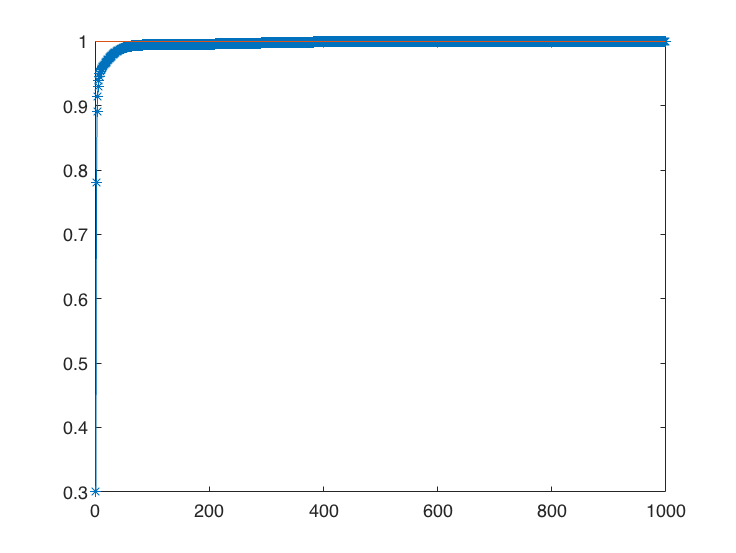

%És interessant estudiar com evoluciona: delta^k/delta^k-1
ratio = delta(2:end) ./ delta(1:end-1);
plot(ratio,'-*')
hold on
plot(rhoGS * ones(size(ratio)))
hold off

tempsGaussSeidel = [tempsGaussSeidel3;tempsGaussSeidel4;tempsGaussSeidel10];

% Càlculs per fer n = 15 //no funciona, el mètode deixa de ser convergent 
% i passa a ser divergent, per tant tenim un problema quan augmentem el
% nombre de variables en el nostre sistema

e) Consulteu la documentació de Matlab®: [Measure the Performance of Your Code](https://es.mathworks.com/help/matlab/matlab_prog/measure-performance-of-your-program.html?searchHighlight=cputime&s_tid=srchtitle#buw2ygr), i [Techniques to Improve Performance](https://es.mathworks.com/help/matlab/matlab_prog/techniques-for-improving-performance.html?searchHighlight=Techniques%20to%20Improve%20Performance&s_tid=srchtitle). Afegiu el còmput del temps en els tres tòpics treballats. Presenteu els resultats en taules. 

table(tempsGauss,tempsSolve,tempsGaussSeidel, 'VariableNames',{'Temps Mètode Gauss','Temps Mètode Solve', 'Temps Mètode Gauss-Seidel'}, 'RowNames',{'n=3','n=4','n=10'})

ans = 3×3 table
            Temps Mètode Gauss    Temps Mètode Solve    Temps Mètode Gauss-Seidel
            __________________    __________________    _________________________

    n=3          0.017952             0.0041231                  0.25798         
    n=4         0.0080258             0.0036138                 0.042564         
    n=10         0.015068             0.0085257                 0.042569         


f) Comenteu els avantatges i els inconvenients dels tres mètodes i l’evolució dels resultats quan 𝑛 es fa gran.

Tal i com podem veure a la taula anterior, hem pogut notar que pel mètode de linsolve que implementa MATLAB el temps d'execució a mesura que n es fa gran es manté constant al llarg del temps tot i augmentar la mida de la matriu. Ja que el temps que triguen aquests algorismes implementats al programari de MATLAB és molt menor que si el implementem nosaltres, a causa del suport de Vector Processing (processament paral·lel) quan MATLAB tracta amb les matrius.

D'altra banda, també hem pogut veure que a mesura que augmentem la mida de la matiu, i.e el nombre de variables que entren en joc en el sistema d'equacions, el mètode de Gauss-Seidel, per n = 15, passa a ser divergent, per tant aquest mètode iteratiu pateix el problema de la convergència. I no és un mètode que ens interessi escollir alhora de resoldre el sistemes.

També hem pogut veure, que el mètode d'eliminació gaussiana, en mitjana aconseguix un millor temps que el mètode iteratiu de Gauss-Seidel. Ja que l'eficiència del mètode d'eliminació gaussiana depèn del nombre de càlculs implicats en la solució de l'equació lineal simultània. A mesura que augmenta el nombre de càlculs; l'eficiència del mètode d'eliminació gaussiana disminueix i viceversa a causa que l'algorisme ha trigat més temps en la substitució cap enrere.

Funció per resoldre sistemes lineals per eliminació gaussiana sense pivotament.

function x = ElimGaussSensePivot(A, b)
[n, n] = size(A);    
[n, k] = size(b);
x = zeros(n,k);      
for i = 1:n-1
    m = -A(i+1:n,i)/A(i,i);
    A(i+1:n,:) = A(i+1:n,:) + m*A(i,:);
    b(i+1:n,:) = b(i+1:n,:) + m*b(i,:);
end;
x(n,:) = b(n,:)/A(n,n);
for i = n-1:-1:1
    x(i,:) = (b(i,:) - A(i,i+1:n)*x(i+1:n,:))/A(i,i);
end
end